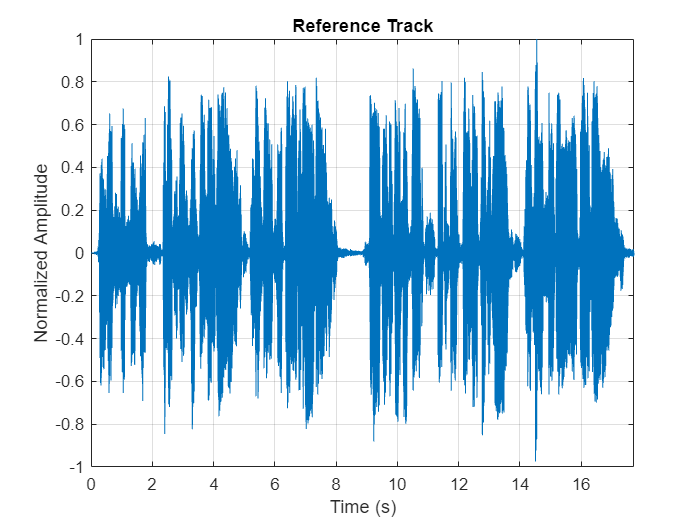

%TIME BASED PLOTS
%get the sample
[ref,Fs] = audioread("reference.wav");
ref = ref(:,1);
Ts = 1/Fs;
[test,Fs] = audioread("test.wav");
test = test(:,1);

%creating index
n = (1:length(ref));

%Time Plots
figure;
plot(n*Ts,ref);
title("Reference Track");
ylabel("Normalized Amplitude")
xlabel("Time (s)");
grid on
xlim([0 850910*Ts])

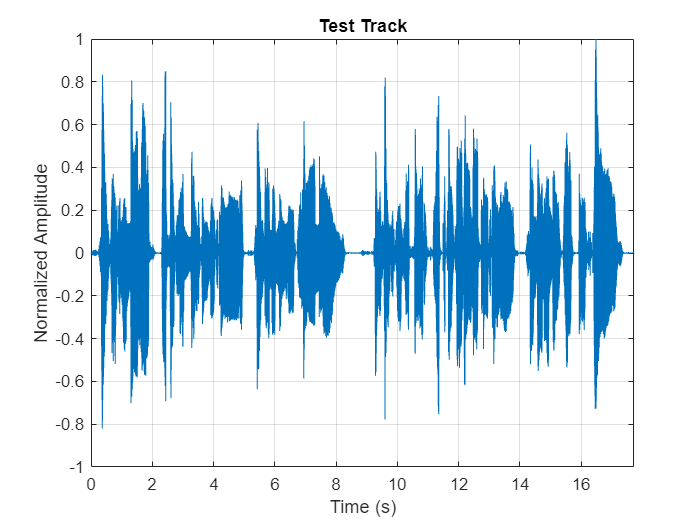


figure;
plot(n*Ts,test);
title("Test Track");
ylabel("Normalized Amplitude")
xlabel("Time (s)");
grid on
xlim([0 850910*Ts])

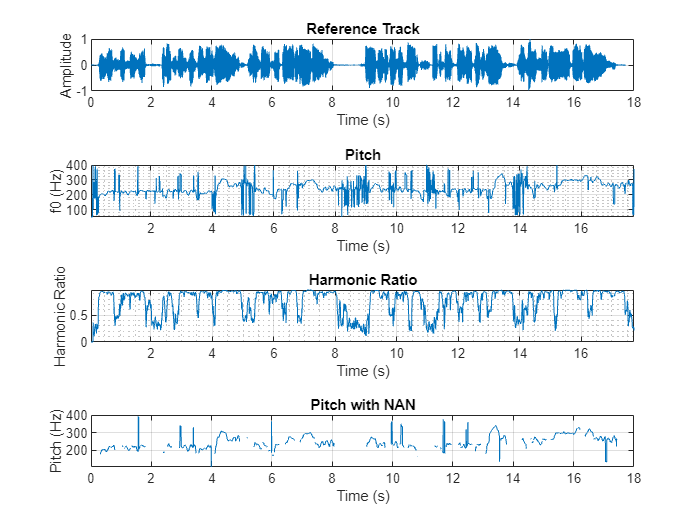


%PITCH STUFF
    winLength = round(0.05*Fs);
    overlapLength = round(0.045*Fs);
    figure
    tiledlayout(4,1)

    %Time Signal
    nexttile
    t = (0:length(ref)-1)/Fs;
    plot(t,ref)
    title("Reference Track")
    xlabel("Time (s)")
    ylabel("Amplitude")
    grid on

    %Pitch
    [f0ref,idx] = pitch(ref,Fs,Method="SRH",WindowLength=winLength,OverlapLength=overlapLength);
    nexttile
    pitch(ref,Fs,Method ="SRH",WindowLength=winLength,OverlapLength=overlapLength);
    title("Pitch")

    %Harmonic Ratio
    nexttile
    hr = harmonicRatio(ref,Fs,Window=hamming(winLength,"periodic"),OverlapLength=overlapLength);
    f0refNAN = f0ref;
    f0refNAN(hr<0.8) = NaN;
    harmonicRatio(ref,Fs,Window=hamming(winLength,"periodic"),OverlapLength=overlapLength);
    title("Harmonic Ratio")

    %Pitch With NAN
    nexttile
    plot (idx/Fs,f0refNAN);
    xlabel("Time (s)")
    ylabel("Pitch (Hz)")
    title("Pitch with NAN")
    grid on

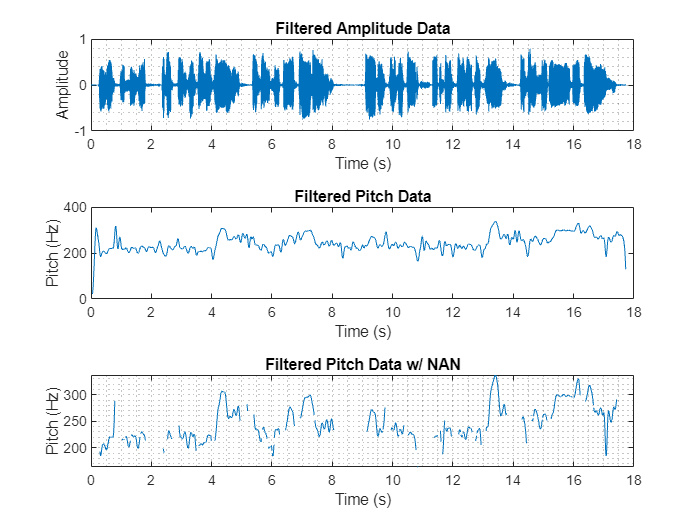


%Filtered Reference
    figure
    tiledlayout(3,1)
    refSmooth = lowpass(ref,.0015);
    nexttile
    plot(n*Ts,refSmooth);
    xlabel("Time (s)")
    ylabel("Amplitude")
    title("Filtered Amplitude Data")
    grid minor
    %sound(refSmooth,Fs);
    
    nexttile
    pitch(refSmooth,Fs)
%Pitch with filter applied
    [f0smoothed,idx2] = pitch(refSmooth,Fs,Method="SRH",WindowLength=winLength,OverlapLength=overlapLength);
    f0smoothed = lowpass(f0smoothed,.0005);
    plot(idx2/Fs,f0smoothed)
    xlabel("Time (s)")
    ylabel("Pitch (Hz)")
    title("Filtered Pitch Data")
%Pitch with NAN
    nexttile
    f0smoothedNAN =f0smoothed;
    f0smoothedNAN(hr< 0.8) = nan;
    plot(idx2/Fs,f0smoothedNAN);
    xlabel("Time (s)")
    ylabel("Pitch (Hz)")
    title("Filtered Pitch Data w/ NAN")
    grid minor

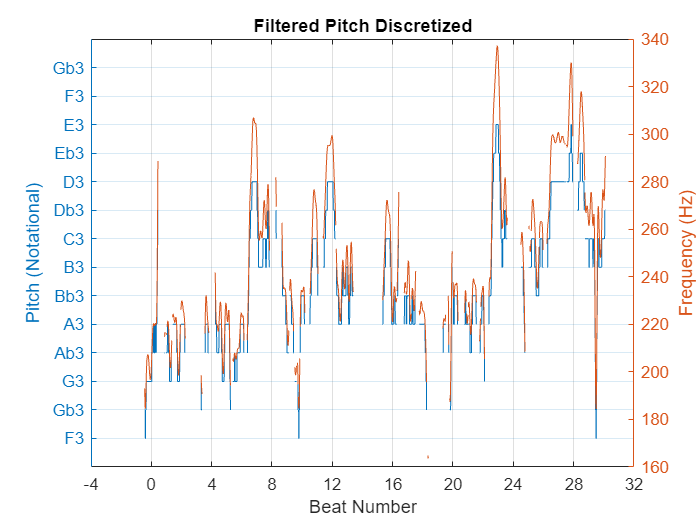


%Frequency to note stuff
    figure
    note = freq2note(f0smoothed(:,1));
    note(hr<0.8)=nan;
    bps=107/60;
    beatLength = 0.5607;
    offset = .545;
    yyaxis left
    plot((idx2/Fs-offset)/beatLength,note);
    title("Filtered Pitch Discretized")
    grid on
    xlabel("Beat Number");
    ylabel("Pitch (Notational)");
    ylim([40 55]);
    xlim([-4 32]);
    yticks([41 42 43 44 45 46 47 48 49 50 51 52 53 54]);
    xticks([-4 0 4 8 12 16 20 24 28 32 ]);
    yticklabels({'F3','Gb3','G3','Ab3','A3','Bb3','B3','C3','Db3','D3','Eb3','E3' 'F3',' Gb3'});
    yyaxis right
    plot((idx2/Fs-offset)/beatLength,f0smoothedNAN);
    ylabel("Frequency (Hz)")

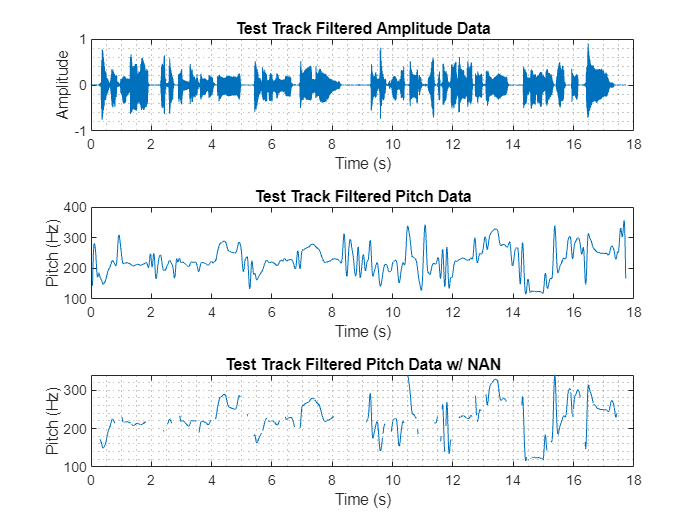

%Test Track Process
    %Filtered Reference
        figure
        tiledlayout(3,1)
        testSmooth = lowpass(test,.0015);
        nexttile
        plot(n*Ts,testSmooth);
        xlabel("Time (s)")
        ylabel("Amplitude")
        title("Test Track Filtered Amplitude Data")
        grid minor
        %sound(testSmooth,Fs);
        nexttile
        pitch(testSmooth,Fs)
    %Pitch with filter applied
        [f0smoothedT,idx2] = pitch(testSmooth,Fs,Method="SRH",WindowLength=winLength,OverlapLength=overlapLength);
        f0smoothedT = lowpass(f0smoothedT,.0005);
        plot(idx2/Fs,f0smoothedT)
        xlabel("Time (s)")
        ylabel("Pitch (Hz)")
        title("Test Track Filtered Pitch Data")
    %Pitch with NAN
        nexttile
        f0smoothedNANT =f0smoothedT;
        f0smoothedNANT(hr< 0.8) = nan;
        plot(idx2/Fs,f0smoothedNANT);
        xlabel("Time (s)")
        ylabel("Pitch (Hz)")
        title("Test Track Filtered Pitch Data w/ NAN")
        grid minor

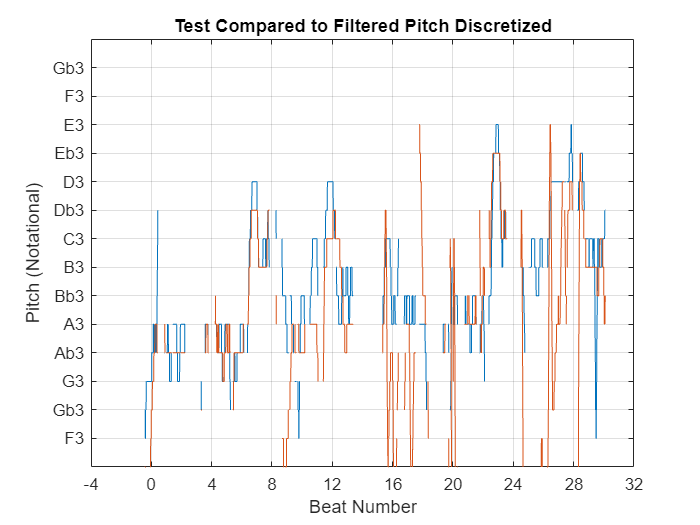

%TEST TRACK Frequency to note stuff
    figure
    noteT = freq2note(f0smoothedT(:,1));
    noteT(hr<0.8)=nan;
    plot((idx2/Fs-offset)/beatLength,note);
    title("Test Compared to Filtered Pitch Discretized")
    grid on
    xlabel("Beat Number");
    ylabel("Pitch (Notational)");
    ylim([40 55]);
    xlim([-4 32]);
    yticks([41 42 43 44 45 46 47 48 49 50 51 52 53 54]);
    xticks([-4 0 4 8 12 16 20 24 28 32 ]);
    yticklabels({'F3','Gb3','G3','Ab3','A3','Bb3','B3','C3','Db3','D3','Eb3','E3' 'F3',' Gb3'});
    hold on
    plot((idx2/Fs-offset)/beatLength,noteT);
    hold off

% %SPEECH DETECTION
% figure
% tiledlayout(2,1);
% ref = ref(1:length(ref),1);
% 
% 
%     %settings
%     windowDuration = 0.1; % seconds
%     numWindowSamples = round(windowDuration*Fs);
%     win = hamming(numWindowSamples,'periodic');
% 
%     percentOverlap = 29;
%     overlap = round(numWindowSamples*percentOverlap/100);
% 
%     mergeDuration = 0.24;
%     mergeDist = round(mergeDuration*Fs);
% 
% nexttile
% detectSpeech(ref,Fs,"Window",win,"OverlapLength",overlap,"MergeDistance",mergeDist); %graph
% 
% nexttile
% 
% plot(n*Ts,ref);
% title("Reference Track");
% xlabel("Time (s)");
% grid on
% xlim([0 850910*Ts])
% 
% %indices stuff
% f0ref = [];
% chunkz = detectSpeech(ref,Fs,"Window",win,"OverlapLength",overlap,"MergeDistance",mergeDist); %getting indices
% 
% for ii = 1:size(chunkz,1)
%         speechSegment = ref(chunkz(ii,1):chunkz(ii,2));
%         f0ref = [f0ref;pitch(speechSegment,Fs)];
% end
% figure
% 
% numBins = 20;
% histogram(f0ref,numBins,Normalization="probability");
% xlabel("Pitch(Hz)")
% ylabel("Probability")